clear all
data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

%data.Properties.VariableNames
%unique(data.ContactStressAmplitude_MPa_);
%groupcounts(data, "ContactStressAmplitude_MPa_");

# **Parameter Estimation Using in-built MATLAB mle **

% a = shape parameter 
% b = scale parameter 
% c = location parameter 
stress_levels = unique(data.ContactStressAmplitude_MPa_);
num_stress_levels = numel(stress_levels); 
max_r_array = zeros(num_stress_levels, 1)

max_r_array =      0
     0
     0
     0



a_estimates = zeros(num_stress_levels,1)

a_estimates =      0
     0
     0
     0


b_estimates = zeros(num_stress_levels,1)

b_estimates =      0
     0
     0
     0


c_estimates = zeros(num_stress_levels,1)

c_estimates =      0
     0
     0
     0


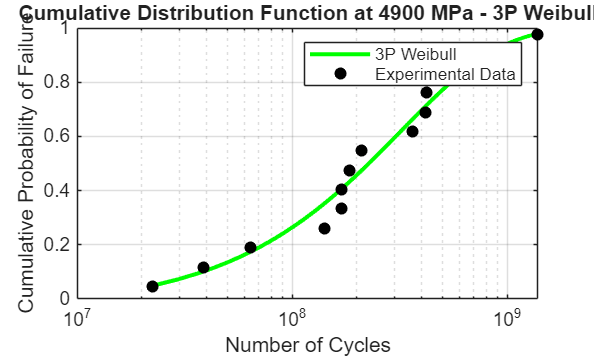

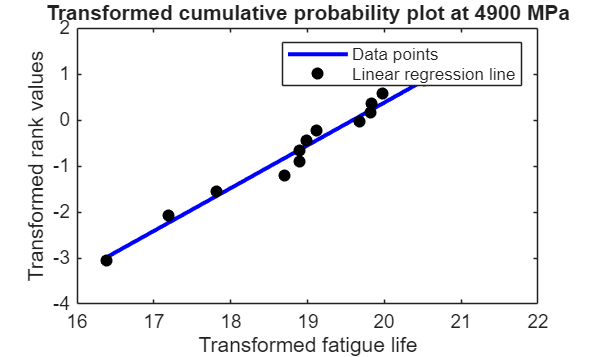

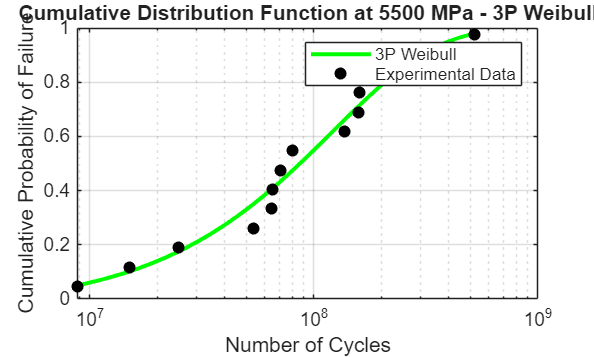

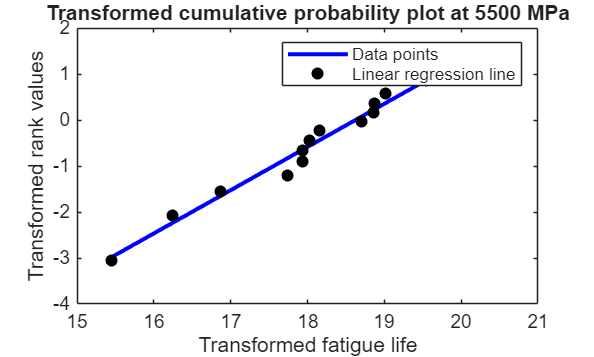

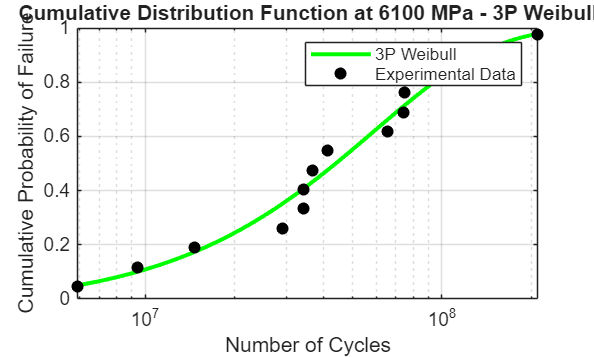

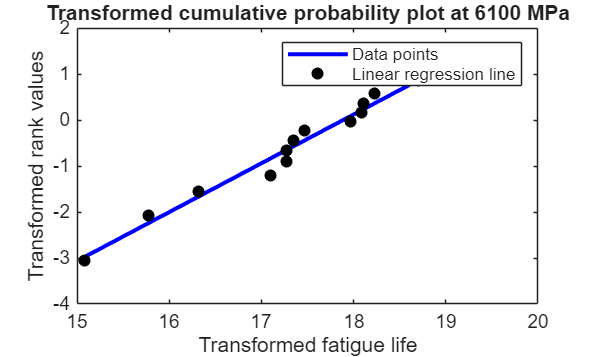

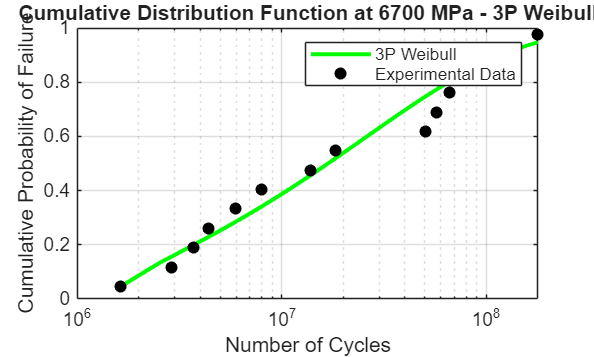

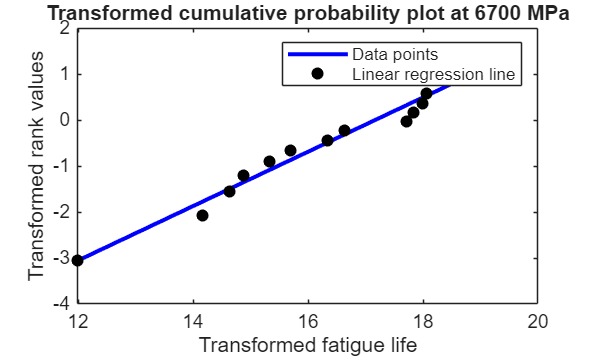

% for b < 1

for j = 1:num_stress_levels
    current_stress = stress_levels(j);
    life_j = data.NumberOfCycles(data.ContactStressAmplitude_MPa_ == stress_levels(j));
    life_j_sorted = sort(life_j);
    num_observations_j = numel(life_j_sorted);
    observation_ranks = linspace(1, num_observations_j, num_observations_j);
    F_j = ((observation_ranks - 0.35) / num_observations_j)'; % using EV for j
    Y_j = log(-log(1 - F_j));

    max_r_j = 0;
    min(life_j);
    c_range_j = linspace(0, 0.999* min(life_j), 100000);
    for k = 1:numel(c_range_j)
        X_k = log(life_j_sorted - c_range_j(k));
        r_2PW_matrix = corrcoef(X_k, Y_j); % calculates correlation coeffiecient matrix
        r_2PW = r_2PW_matrix(1, 2);
        %r_2PW = r_2PW ^ 2;

        if r_2PW > max_r_j
            max_r_j = r_2PW;
            best_c = c_range_j(k);
            X_max_j = X_k;
        end
    end

    fitted_line = polyfit(X_max_j, Y_j, 1);
    reg_slope = fitted_line(1);
    reg_intercept = fitted_line(2);
    c_estimates(j) = best_c;
    b_estimates(j) = reg_slope;
    a_estimates(j) = exp(-reg_intercept/b_estimates(j));
    B1_lives_3PW(j) = c_estimates(j) + a_estimates(j) * ((-log(0.99)) ^ (1/b_estimates(j)));
    max_r_array(j) = max_r_j;
    
    weib3_cdf = @(x, a, b, c) (x > c) .* (1 - exp(-((x - c) / a).^b)); % from matlab documentation
    life_j_lin = linspace(min(life_j), max(life_j), 200);
    cdf_3PW = weib3_cdf(life_j_lin, a_estimates(j), b_estimates(j), c_estimates(j));

    figure 
    plot(life_j_lin, cdf_3PW, 'Color', 'g', 'LineWidth', 2, 'LineStyle','-');
    hold on 
    scatter(life_j_sorted, F_j, 'filled', 'o','k');
    xlabel('Number of Cycles');
    ylabel('Cumulative Probability of Failure');
    title(sprintf('Cumulative Distribution Function at %d MPa - 3P Weibull', current_stress)); % got assitance on writing this line from chatgpt, recommended sprintf ** intially tried to concatenate which didn't work
    legend('3P Weibull', 'Experimental Data');
    set(gca,'xscale','log');
    grid on


    % plot the regression to see transformed data against fitted line
    Y_fit = reg_slope * X_max_j + reg_intercept; 
    figure 
    plot(X_max_j, Y_fit, 'Color', 'b', 'LineWidth', 2);
    hold on 
    scatter(X_max_j, Y_j, 'filled', 'o', 'k')
    xlabel('Transformed fatigue life');
    ylabel('Transformed rank values');
    title(sprintf('Transformed cumulative probability plot at %d MPa', current_stress));
    legend('Data points', 'Linear regression line')
end 



B1_lives_3PW = B1_lives_3PW'

B1_lives_3PW = 1.0e+07 *

    1.1776
    0.4574
    0.3099
    0.1482


max_r_array

max_r_array =     0.9898
    0.9898
    0.9897
    0.9872


a_estimates

a_estimates = 1.0e+08 *

    3.2277
    1.2259
    0.5863
    0.2858


b_estimates 

b_estimates =     0.9305
    0.9394
    1.0615
    0.5908


c_estimates 

c_estimates = 1.0e+06 *

    9.4748
    3.6579
    2.3294
    1.4702



results_3PW = table(stress_levels, a_estimates, b_estimates, c_estimates, B1_lives_3PW, max_r_array)

results_3PW = 4×6 table
    stress_levels    a_estimates    b_estimates    c_estimates    B1_lives_3PW    max_r_array
    _____________    ___________    ___________    ___________    ____________    ___________

        4900         3.2277e+08       0.93053      9.4748e+06      1.1776e+07       0.98975  
        5500         1.2259e+08        0.9394      3.6579e+06      4.5737e+06       0.98977  
        6100         5.8632e+07        1.0615      2.3294e+06      3.0987e+06       0.98966  
        6700         2.8581e+07       0.59082      1.4702e+06      1.4821e+06       0.98716  
